clear all


%%%%%%%% Блок создания массива классических каналов и квантового канала %%%%%%%%%%%
CH_NUM = 40;
CH_SPAC = 100;
 
edfa_params_paper_1;

FREQ_ARRAY = 191.6 + (1:CH_NUM) * CH_SPAC * 10 ^ (-3);

WL_ARRAY = c./(FREQ_ARRAY * 10 ^ 12) * 10 ^ 9;

WL_ARRAY = fliplr(WL_ARRAY);

% WL_ARRAY = 1530 + (1:CH_NUM) * 1 ;
% 
% FREQ_ARRAY = c./(WL_ARRAY * 10 ^ 12) * 10 ^ 9;

% FREQ_ARRAY = 192 + (1:CH_NUM) * CH_SPAC * 10 ^ (-3);
% 
% WL_ARRAY = c./(FREQ_ARRAY * 10 ^ 12) * 10 ^ 9;
% 
% WL_ARRAY = fliplr(WL_ARRAY);

%%%%%%%% Блок рассчета требований к EDFA и мощности каналов %%%%%%%%
EM_ARRAY = zeros(1,CH_NUM);
AB_ARRAY = zeros(1,CH_NUM);

for k = 1:length(WL_ARRAY)
    [EM_ARRAY(k),AB_ARRAY(k)] = get_EM_AB(WL_ARRAY(k),'EM_PAPER(1).csv','AB_PAPER(1).csv',0) ;
end
clear 'k'

%%%%%%% Блок рассчета overlap integral %%%%%%%%%%%%%%%%%%
% 
for k = 1:length(WL_ARRAY)
    Gamma_s(k) = Function_Overlap(Fiber,WL_ARRAY(k) * 10^(-9),1);
end
clear 'k'
Gamma_p = Function_Overlap(Fiber,wl_p * 10^(-9),1);

% Gamma_s = ones(1,CH_NUM) * 0.58;
% Gamma_p = 0.62;

% for k = 1:length(WL_ARRAY)
%     v(k) = 2*pi/WL_ARRAY(k)*10^9*r_fiber*(n1^2 - n2^2)^(1/2);
%     w(k) = (0.65 + 1.619/v(k)^(3/2) + 2.879/v(k)^6)*r_fiber;
%     Gamma_s(k) = 1 - exp(-r_fiber/w(k));
% end
% clear 'k'
% 
% vp = 2*pi/wl_p*10^9*r_fiber*(n1^2 - n2^2)^(1/2);
% wp = (0.65 + 1.619/vp^(3/2) + 2.879/vp^6)*r_fiber;
% Gamma_p = 1 - exp(-r_fiber/wp);
% 
% clear 'vp' 'v' 'w' 'wp'

T = 1*10^(-3);
span = [0 T];
y0 = 0;

%%%%%%%%%%%%%%%%%%%% Multi wavelength model %%%%%%%%%%%%%%%
%%%%%% Условия приемника %%%%%%%%%%%%

P_min = - 23; %dBm
OSNR_min = 9; %dB
IL = 8; % потери в приемнике dBm
Rx = - 23; % чувствительность приемника dBm

%%%%%%%%% PARAMS PART %%%%%%%%%%%%%%%%%%%%%%
P_p_dBm = 25; %dBm
P_s_in_0 = Rx + IL; %dBm
P_s_const = -25; %используемая мощность сигнала для зависимости от длины

Losses = 10 ^ (( IL ) / 10);

delta_P = -1;
M = 500; %число рассматриваемых длин усилителя
N = 11; % число рассматриваемых мощностей сигналов
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

P_s_in_ARRAY = zeros(1,N);
L_ARRAY = zeros(1,M);
GAIN = zeros(N,CH_NUM);
GAIN_L = zeros(M,CH_NUM);
N_sp = zeros(N,CH_NUM);
P_ASE = zeros(N,CH_NUM);
OSNR = zeros(N,CH_NUM);
P_s_dBm = zeros(1,N);
OSNR_gr = zeros(1,CH_NUM);
P_gr = zeros(1,CH_NUM);
OBW = zeros(1,CH_NUM);
MEDIUM = zeros(1,CH_NUM);
DELTA_M = zeros(1,CH_NUM);
index_top = [];
P_out = zeros(1,CH_NUM);
P_optimal = 0;
P_on_detector = zeros(1,CH_NUM);



for k = 1:length(WL_ARRAY)
    OBW(k) = BWNmToGHz(BW * 10^(-9),WL_ARRAY(k) * 10^(-9)) ;% Частотное пропускание детектора
end
clear 'k'

P_p = 10 ^ (( P_p_dBm ) / 10) / 1000;
P_s = 10 ^ (( P_s_const ) / 10) / 1000;

for g = 1:N  
    P_s_dBm(g) = P_s_in_0 + delta_P * (g-1);
    P_s_in_ARRAY = 10 .^ (( P_s_dBm ) ./ 10) ./ 1000;
end
clear 'g'

for k = 1:length(WL_ARRAY)
    OSNR_gr(k) = OSNR_min;
    P_gr(k) = P_min;
end
clear 'k'

%%%%%%% Рассчет зависимости усиления от длины усилителя %%%%%%%

for g = 1:M
    L_ARRAY(g) = (g-1)/10;
end
clear 'g'

for g = 1:M
    
    [t_m , N2_m] = ode15s(@(t_m,N2_m) edfa_eqs_paper_1(t_m,N2_m,L_ARRAY(g),EM_ARRAY,AB_ARRAY,WL_ARRAY,P_p,P_s,CH_NUM,Gamma_s,Gamma_p) ,span,y0);
       
    for u = 1:length(WL_ARRAY)
    
        GAIN_L(g,u) = exp(Gamma_s(u) * (EM_ARRAY(u) + AB_ARRAY(u)) / (4.3429 * rho * A) * N2_m(length(t_m)) - Gamma_s(u) * AB_ARRAY(u) * L_ARRAY(g) / 4.3429);
    
    end    
end

clear 'g' 'u'


for g = 1:M
    MEDIUM(g) = sum(GAIN_L(g,:)) / CH_NUM;
end

for g = 1:M
    DELTA_M(g) = 0;
    for u = 1:CH_NUM
        for k = 1:CH_NUM
            if GAIN_L(g,u) - GAIN_L(g,k) > DELTA_M(g)
               DELTA_M(g) = GAIN_L(g,u) - GAIN_L(g,k);
            end
        end
    end
end
clear 'g'

for g = 1:M
    if MEDIUM(g) > max(MEDIUM)/2
    index_top(end+1) =  g; % Это список индексов столбцов усилений по длинам волн, где среднее значение усиления больше чем половина максимального
    end
end
clear 'g'

delta_opt = DELTA_M(index_top(1));

I = 1;
for g = 1:length(index_top)
    if DELTA_M(index_top(g)) < delta_opt
        delta_opt = DELTA_M(index_top(g));
        I = index_top(g);
    end
end
clear 'g'

[m,II] = max(MEDIUM);
[mm,III] = max(GAIN_L);
[mmm,IIII] = max(mm);

'Мощность накачаки  mW'

ans = 'Мощность накачаки  mW'

P_p * 1000 

ans = 316.2278

'Оптимальная для равного усиления длина m'

ans = 'Оптимальная для равного усиления длина m'

L_ARRAY(I)

ans = 47.2000

'Оптимальная для наибольшего общего усиления длина m'

ans = 'Оптимальная для наибольшего общего усиления длина m'

L_ARRAY(II)

ans = 32.9000

'Оптимальная для наибольшего частного усиления длина m'

ans = 'Оптимальная для наибольшего частного усиления длина m'

L_ARRAY(III(IIII))

ans = 23.8000

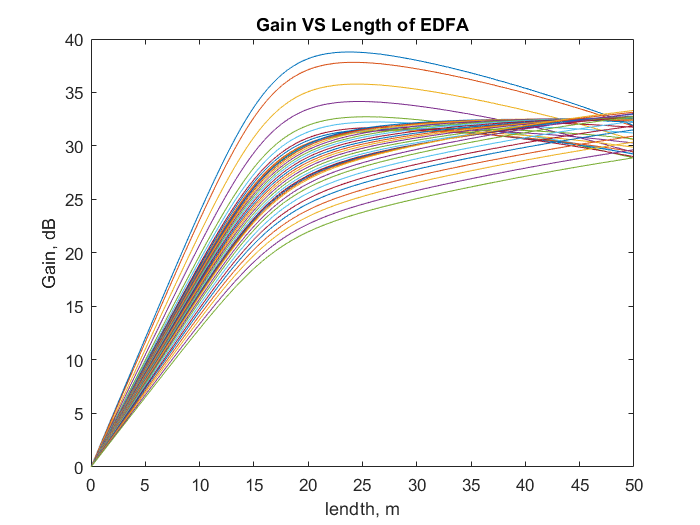







for u = 1:CH_NUM
    figure(1)
    plot(L_ARRAY,10*log10(GAIN_L(:,u)))
    hold on
end


clear 'u'

title('Gain VS Length of EDFA')
ylabel('Gain, dB')
xlabel('lendth, m')

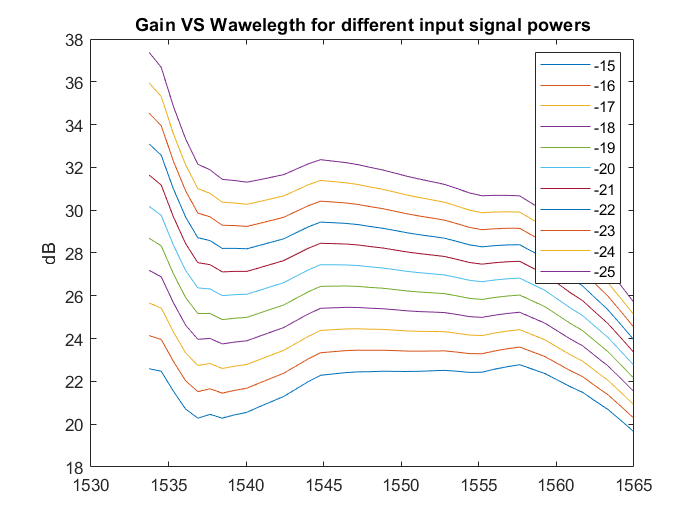

% figure(2)
% plot(L_ARRAY,DELTA_M)
% 
% figure(3)
% plot(L_ARRAY,10*log10(MEDIUM))
% 
% figure(4)
% plot(L_ARRAY,10*log10(MEDIUM_M))


%%%% Рассчет модели для разных мощностей сигналов %%%%%%%%

L = L_ARRAY(II);

a = 0;
for g = 1:N
        
    [t_m , N2_m] = ode15s(@(t_m,N2_m) edfa_eqs_paper_1(t_m,N2_m,L,EM_ARRAY,AB_ARRAY,WL_ARRAY,P_p,P_s_in_ARRAY(g),CH_NUM,Gamma_s,Gamma_p) ,span,y0);
       
       for u = 1:length(WL_ARRAY)
    
           GAIN(g,u) = exp(Gamma_s(u) * (EM_ARRAY(u) + AB_ARRAY(u)) / (4.3429 * rho * A) * N2_m(length(t_m)) - Gamma_s(u) * AB_ARRAY(u) * L / 4.3429);
           
           N_sp(g,u) = N2_m(length(t_m)) / ( N2_m(length(t_m)) - AB_ARRAY(u)/EM_ARRAY(u) * (rho*L*A - N2_m(length(t_m))));
           
           if N_sp(g,u) < 0
               
               P_ASE(g,u) = 2 * h * c / (WL_ARRAY(u) * 10^(-9)) * N_sp(g,u) * OBW(u) * (GAIN(g,u) - 1);
           
               P_out(g,u) = P_s_in_ARRAY(g) * GAIN(g,u);
           
               P_on_detector(g,u) = P_s_in_ARRAY(g) * GAIN(g,u) / Losses ;

               OSNR(g,u) = (P_on_detector(g,u))/(P_ASE(g,u) / Losses);
               a = a+1;
           else
               P_ASE(g,u) = 2 * h * c / (WL_ARRAY(u) * 10^(-9)) * N_sp(g,u) * OBW(u) * (GAIN(g,u) - 1);
           
               P_out(g,u) = P_s_in_ARRAY(g) * GAIN(g,u);
           
               P_on_detector(g,u) = P_s_in_ARRAY(g) * GAIN(g,u) / Losses ;

               OSNR(g,u) = (P_on_detector(g,u))/(P_ASE(g,u) / Losses);
           end
       end
end   
clear 'g' 'u'  

for g = 1:N
    figure(2)
    plot(WL_ARRAY,10*log10(GAIN(g,:)))
    hold on
end
title('Gain VS Wawelegth for different input signal powers')
legend(string(P_s_dBm))
ylabel('dB')

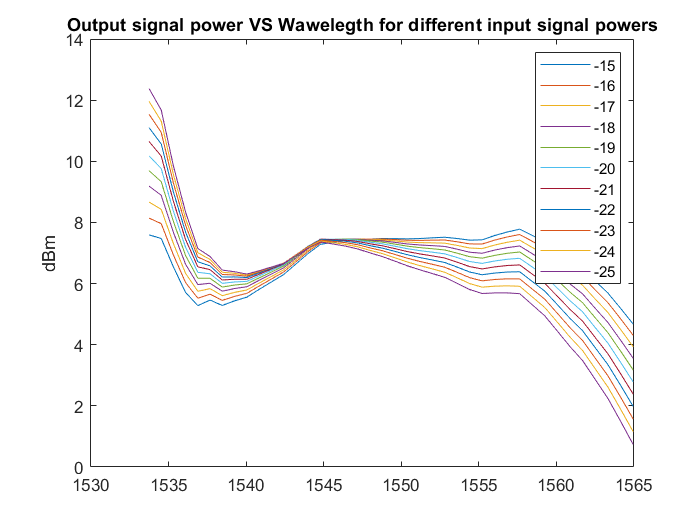

clear 'g' 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%% Блок оценки мощностей в dBm %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for g = 1:N
    figure(3)
    plot(WL_ARRAY,10*log10(P_out(g,:)*10^3))
    hold on
end
title('Output signal power VS Wawelegth for different input signal powers')
legend(string(P_s_dBm))
ylabel('dBm')

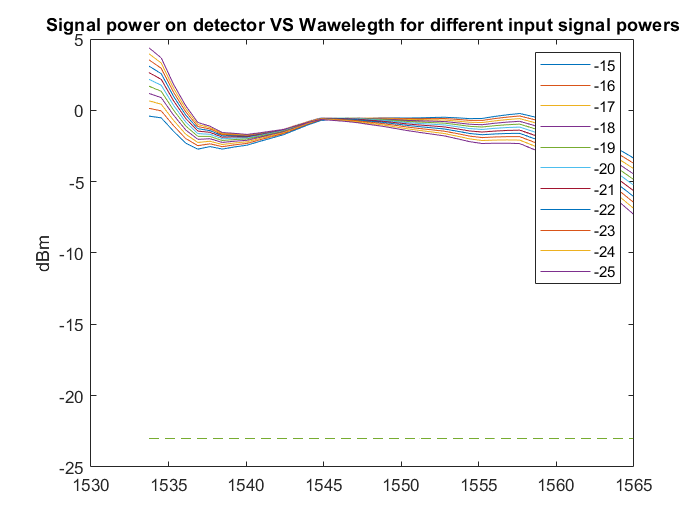

clear 'g'

for g = 1:N
    figure(4)
    plot(WL_ARRAY,10*log10(P_on_detector(g,:)*10^3))
    hold on
end
plot(WL_ARRAY,P_gr,'--')
title('Signal power on detector VS Wawelegth for different input signal powers')
legend(string(P_s_dBm))
ylabel('dBm')

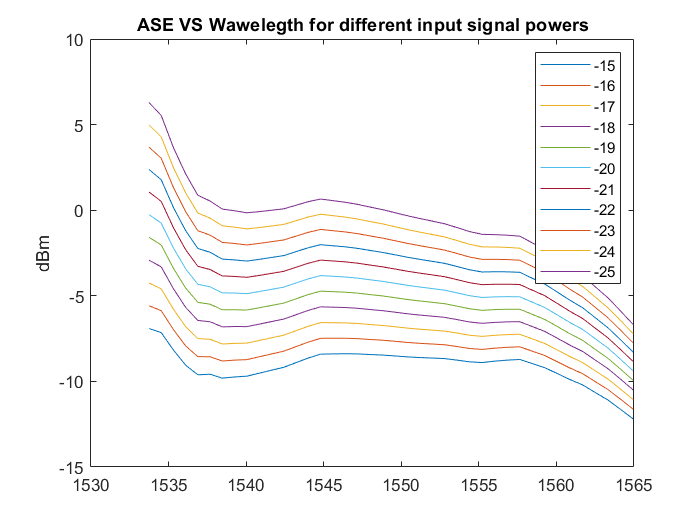

clear 'g'


for g = 1:N
    figure(5)
    plot(WL_ARRAY,10*log10(P_ASE(g,:)*10^3))
    hold on
end

title('ASE VS Wawelegth for different input signal powers')
legend(string(P_s_dBm))
ylabel('dBm')

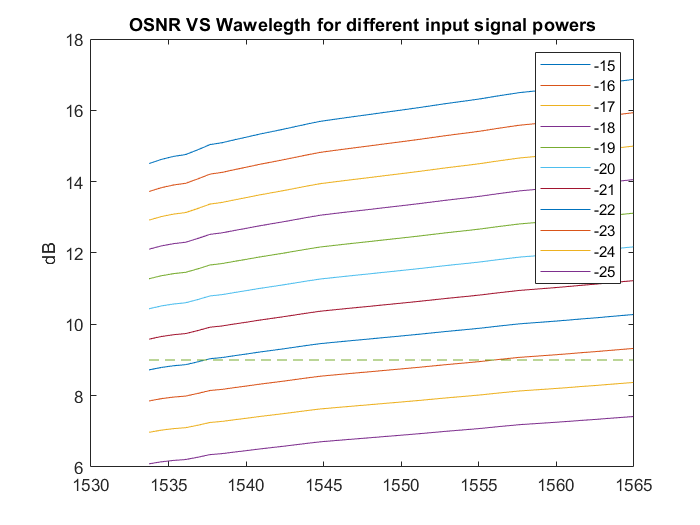

clear 'g'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%% Блок оценки мощностей в Вт %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% for g = 1:N
%     figure(3)
%     plot(WL_ARRAY,P_out(g,:))
%     hold on
% end
% % title('Output signal power VS Wawelegth for different input signal powers')
% title('Output signal power')
% legend(string(P_s_dBm))
% ylabel('Вт')
% clear 'g'
% 
% for g = 1:N
%     figure(4)
%     plot(WL_ARRAY,P_on_detector(g,:))
%     hold on
% end
% plot(WL_ARRAY,10.^(P_gr/10)/1000,'--')
% % title('Signal power on detector VS Wawelegth for different input signal powers')
% title('Signal power on detector')
% legend(string(P_s_dBm))
% ylabel('Вт')
% clear 'g'
% 
% 
% for g = 1:N
%     figure(5)
%     plot(WL_ARRAY,P_ASE(g,:))
%     hold on
% end
% 
% title('ASE VS Wawelegth for different input signal powers')
% legend(string(P_s_dBm))
% ylabel('Вт')
% clear 'g'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%% Конец блока оценки мощностей %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for g = 1:N
    figure(6)
    plot(WL_ARRAY,10*log10(OSNR(g,:)))
    hold on
end
plot(WL_ARRAY,OSNR_gr,'--')
title('OSNR VS Wawelegth for different input signal powers')
legend(string(P_s_dBm))
ylabel('dB')

clear 'g' 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%% Блок поиска оптимальной мощности %%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
P_optimal = Rx + IL;

index_opt_power_osnr = [];
for g = 1:N
    if 10*log10(OSNR(g,:)) >= OSNR_min
        index_opt_power_osnr(end+1) = g;
    end
end
clear 'g' 

index_opt_power_detect = [];
for g = 1:N
    if 10*log10(P_on_detector(g,:)*1000) >= Rx
        index_opt_power_detect(end+1) = g;
    end
end
clear 'g' 

for g = 1:length(index_opt_power_osnr)
    for h = 1:length(index_opt_power_detect)
        if P_s_dBm(index_opt_power_osnr(g)) < P_optimal && index_opt_power_osnr(g) == index_opt_power_detect(h)
           P_optimal = P_s_dBm(index_opt_power_osnr(g))  
        end
    end
end

P_optimal = -16

P_optimal = -17

P_optimal = -18

P_optimal = -19

P_optimal = -20

P_optimal = -21


if P_optimal >= Rx + IL
    "Optimal power wasn't deceted"
end

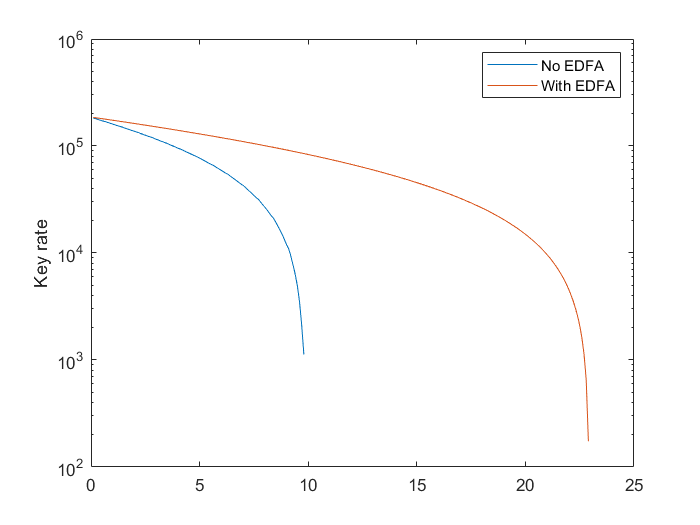

%%%%%%% Блок прохождения через волокно %%%%%%%%%%%

L_fiber = (0:0.1:300);
Rx = - 23; % чувствительность приемника dBm

BW = 15;
wl_q = 1535;

type = 'forward';
alpha = 0.18;

t_gate = 1*10^-9;
de = 0.1;
m = 0.319;
mu0 = 4;
nu = 10^-3;
sigma = 0.99;
dPH = 5*pi/180;
pdark = 1*10^-6;
tau = 1;
rep_rate = 100*10^6;
infT = 1/rep_rate;
N = 2;
ISOL = 110;
beta = 0.3;
gamma = 0.78;
Dc = 18*10^-12/(10^-9*10^3);
dDc = 0.089*10^-12/((10^-9)^2*10^3);
SR = 12.5;

%%%%%% Расчет мощности шумов без EDFA %%%%%%
Power_R = RamanNoisePowerOptimized(CH_NUM,CH_SPAC,Rx,IL,alpha,L_fiber,wl_q,BW,'forward');
Power_LCXT = LCXTPower(CH_NUM, Rx, IL, ISOL);
Power_FWM = PowerFWM(CH_NUM,CH_SPAC,alpha,L_fiber,BW,Rx,beta,gamma,Dc,dDc,SR,IL,wl_q);

PhotNum = PowerToPhotonNumber(Power_R + Power_LCXT + Power_FWM,t_gate,wl_q,de,IL);

[Q_1, K_1] = SecuritySCWQKD(m, tau, de, L_fiber, IL, alpha, nu, dPH, sigma, mu0, pdark, PhotNum, infT, N);

%%%%%% Расчет мощности шумов c EDFA %%%%%%
Power_R_edfa = RamanNoisePowerOptimized(CH_NUM,CH_SPAC,P_optimal,0,alpha,L_fiber,wl_q,BW,'forward');
Power_LCXT_edfa = LCXTPower(CH_NUM, P_optimal, 0, ISOL);
Power_FWM_edfa = PowerFWM(CH_NUM,CH_SPAC,alpha,L_fiber,BW,P_optimal,beta,gamma,Dc,dDc,SR,0,wl_q);

PhotNum = PowerToPhotonNumber(Power_R_edfa + Power_LCXT_edfa + Power_FWM_edfa,t_gate,wl_q,de,IL);

[Q_2, K_2] = SecuritySCWQKD(m, tau, de, L_fiber, IL, alpha, nu, dPH, sigma, mu0, pdark, PhotNum, infT, N);

figure(7)
semilogy(L_fiber,K_1)
hold on
semilogy(L_fiber,K_2)
legend('No EDFA' , 'With EDFA')
ylabel('Key rate')